# Aula_03_ECM307 - Série Trigonométrica de Fourier

Felipe Fazio da Costa; RA: 23.00055-4

## Boas práticas

clear;
close all;
clc;
%%% Limpando todo sistema para início dos calculos

## Função p(t)

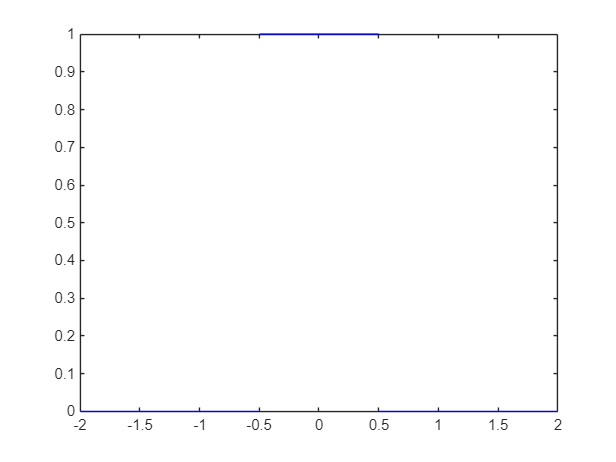

%%% Primeiro período
t1 = -2 : 1e-3 : -0.5;
g1 = zeros(size(t1));  % g1 é 0 para t1

t2 = -0.5 : 1e-3 : 0.5;
g2 = ones(size(t2));  % g2 é 1 para t2

t3 = 0.5 : 1e-3 : 2;
g3 = zeros(size(t3));  % g2 é 1 para t2

%%% Plotagem
plot(t1, g1, 'b');  % Plota o primeiro intervalo em azul
hold on;  % Mantém o gráfico atual
plot(t2, g2, 'b');  % Plota o segundo intervalo em azul
plot(t3, g3, 'b');  % Plota o segundo intervalo em azul

hold off;  % Libera o gráfico para novas plotagens

## Calculando an

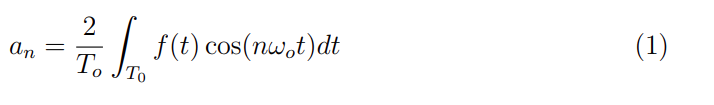

syms n t; % inicialização das variávieis
To = 4; % definindo o valor do período
w = (2 * pi)/To; % defininido w pela fórmula (2*pi)/To

% Calculando an, somente para f(t) = 1, pois o outro valor que adota é 0
an = 2/To * int(1 * cos(n * w * t), t, -0.5, 0.5)

$$an = \frac{2\,\sin\left(\frac{\pi \,n}{4}\right)}{n\,\pi }$$

## Calculando bn

syms n t; % inicialização das variávieis
To = 4; % definindo o valor do período
w = (2 * pi)/To; % defininido w pela fórmula (2*pi)/To

% Calculando bn, somente para p(t) = 1, pois o outro valor que adota é 0
bn = 2/To * int(1 * sin(n * w * t), t, -0.5, 0.5)

$$bn = 0$$

## Calculando a0

syms t; % inicialização das variávieis

% Calculando bn, somente para p(t) = 1, pois o outro valor que adota é 0
a0 = 1/To * int(1 , t, -0.5, 0.5)

$$a0 = \frac{1}{4}$$

## Valor numérico de an e bn:

%% Calculando an
num_an = eval(an)

$$num\_an = \frac{2\,\sin\left(\frac{\pi \,n}{4}\right)}{n\,\pi }$$

## Calculando a função sintetizada para p(t)

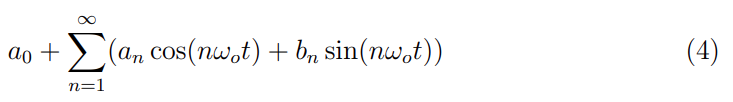

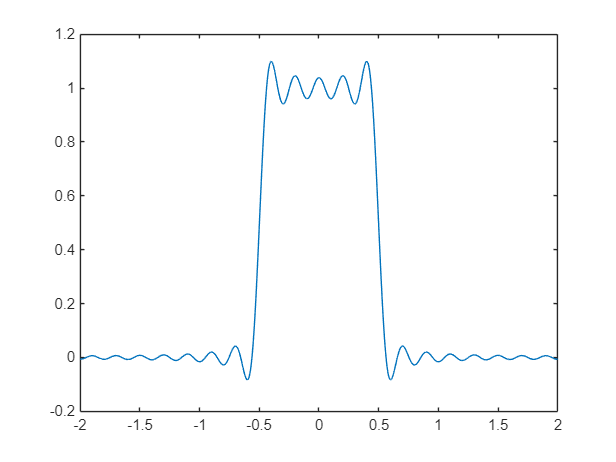

%%% Declarando o número de Harmônicas:
N = 20;
n = 1:1:N;

num_plot_an = eval(num_an);

tempo = -2 : 1e-3 : 2;  % Define o vetor tempo

aux = a0;
% Obtenção do sinal sintetizado
for k = 1:N

    aux  =  aux + num_plot_an(k)*cos(n(k)*w*tempo);
end

gt0_sintetizado = aux;
plot(tempo, gt0_sintetizado)

## Função g(t)

%%% Primeiro período
t1 = 0 : 1e-3 : 1;
g1 = ones(size(t1));  % g1 é 0 para t1

t2 = 1 : 1e-3 : 2;
g2 = ones(size(t2));  % g2 é 1 para t2

Error using whos
Argument must be a text scalar.


t3 = 2 : 1e-3 : 3;
g3 = ones(size(t3));  % g2 é 1 para t2

%%% Plotagem
plot(t1, g1, 'b');  % Plota o primeiro intervalo em azul
hold on;  % Mantém o gráfico atual
plot(t2, g2, 'b');  % Plota o segundo intervalo em azul
plot(t3, g3, 'b');  % Plota o segundo intervalo em azul

hold off;  % Libera o gráfico para novas plotagens

## Calculando an

syms n t; % inicialização das variávieis
To = 4; % definindo o valor do período
w = (2 * pi)/To; % defininido w pela fórmula (2*pi)/To

% Calculando an, somente para f(t) = 1 e f(t) = 2, pois o outro valor que adota é 0
an = 2/To * (int(1 * cos(n * w * t), t, 0, 1) + int(2 * cos(n * w * t), t, 1, 2) + int(1 * cos(n * w * t), t, 2, 3))

$$an = \frac{\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }+\frac{2\,\left(\sin\left(\pi \,n\right)-\sin\left(\frac{\pi \,n}{2}\right)\right)}{n\,\pi }-\frac{\sin\left(\pi \,n\right)-\sin\left(\frac{3\,\pi \,n}{2}\right)}{n\,\pi }$$

## Calculando bn

syms n t; % inicialização das variávieis
To = 4; % definindo o valor do período
w = (2 * pi)/To; % defininido w pela fórmula (2*pi)/To

% Calculando an, somente para f(t) = 1 e f(t) = 2, pois o outro valor que adota é 0
bn = 2/To * (int(1 * sin(n * w * t), t, 0, 1) + int(2 * sin(n * w * t), t, 1, 2) + int(1 * sin(n * w * t), t, 2, 3))

$$bn = \frac{\cos\left(\pi \,n\right)-\cos\left(\frac{3\,\pi \,n}{2}\right)}{n\,\pi }-\frac{2\,\left(\cos\left(\pi \,n\right)-\cos\left(\frac{\pi \,n}{2}\right)\right)}{n\,\pi }+\frac{2\,{\sin\left(\frac{\pi \,n}{4}\right)}^{2}}{n\,\pi }$$

## Calculando a0

syms t; % inicialização das variávieis

% Calculando bn, somente para p(t) = 1, pois o outro valor que adota é 0
a0 = 1/To * (int(1 , t, 0, 1) + int(2 , t, 1, 2) + int(1 , t, 2, 3))

$$a0 = 1$$

## Valor numérico de an e bn:

%% Calculando an
num_an = eval(an)

$$num\_an = \frac{2\,\sin\left(\pi \,n\right)-2\,\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }+\frac{\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }-\frac{\sin\left(\pi \,n\right)-\sin\left(\frac{3\,\pi \,n}{2}\right)}{n\,\pi }$$


%% Calculando an
num_bn = eval(bn)

$$num\_bn = \frac{\cos\left(\pi \,n\right)-\cos\left(\frac{3\,\pi \,n}{2}\right)}{n\,\pi }+\frac{2\,{\sin\left(\frac{\pi \,n}{4}\right)}^{2}}{n\,\pi }-\frac{2\,\cos\left(\pi \,n\right)-2\,\cos\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

## Calculando a função sintetizada para p(t)

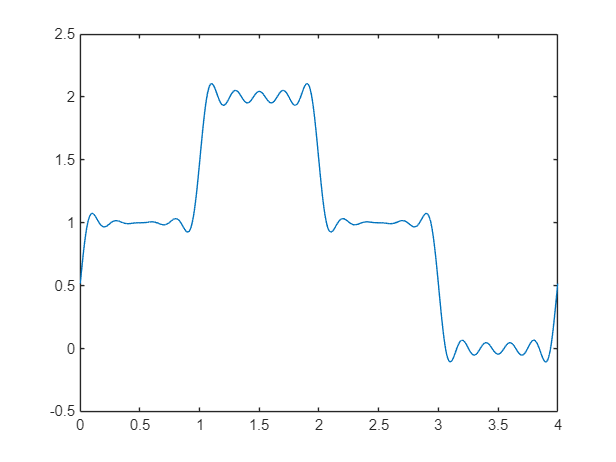

%%% Declarando o número de Harmônicas:
N = 20;
n = 1:1:N;

num_plot_an = eval(num_an);
num_plot_bn = eval(num_bn);

tempo = 0 : 1e-3 : 4;  % Define o vetor tempo

aux = a0;
% Obtenção do sinal sintetizado
for k = 1:N

    aux  =  aux + num_plot_an(k)*cos(n(k)*w*tempo) + num_plot_bn(k)*sin(n(k)*w*tempo);
end

gt0_sintetizado = aux;
plot(tempo, gt0_sintetizado)